# Module 9

## Problem 9.3.26

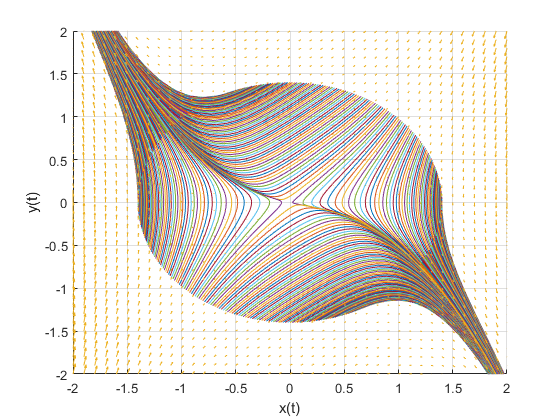


xgv = -2:0.1:2;
ygv = -2:0.1:2;

[X,Y] = meshgrid(xgv,ygv);

gamma = 0.8;

X_dot = -Y;
Y_dot = -gamma*Y - X.^3 + 0.35*X.^2 - 0.3*X;
quiver(X,Y,X_dot,Y_dot)

hF = figure;
hA = axes('Parent',hF,'NextPlot','add');
hA.XGrid = 'on';
hA.YGrid = 'on';

for theta = (0:0.05:20)*pi/10
    x0 = 1.4*[cos(theta);sin(theta)];
    f = @dxdt;
    [t,x] = ode45(f,[0 30],x0);
    plot(x(:,2),x(:,1))
end

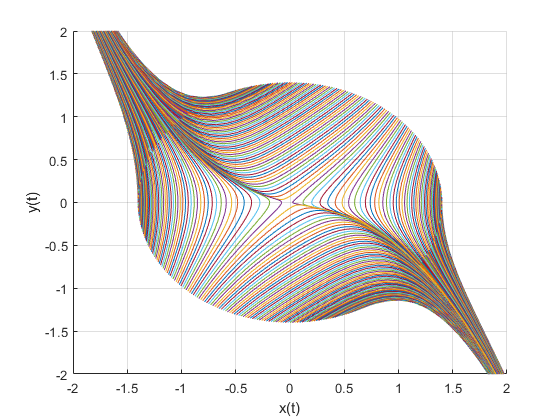


hA.XLim = [-2 2];
hA.YLim = [-2 2];
hA.XLabel.String = 'x(t)';
hA.YLabel.String = 'y(t)';

clc

function d = dxdt(t,x,gamma)
    gamma = 0.8;%1; %5.138;
    d = [-gamma -0.3; -1 0]*x + [0 0.35; 0 0]*x.^2 + [0 -1; 0 0]*x.^3;
end
